# Voice Codecs Project report

#### Team members: 

- Ahmed Mohamed 202200294

- Ahmed Salah 20220212

- Ali 

- Abdelhady 201900

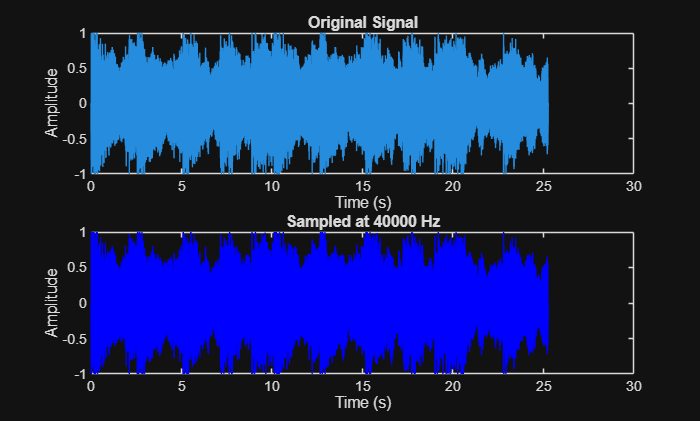

[inputAudio, Fm] = audioread('input_audio_1.wav');
inputAudio = inputAudio(:,1);
sound(inputAudio,Fm);

[time_vector, sampled_signal, Fs] = sampler(inputAudio, 40000, Fm);

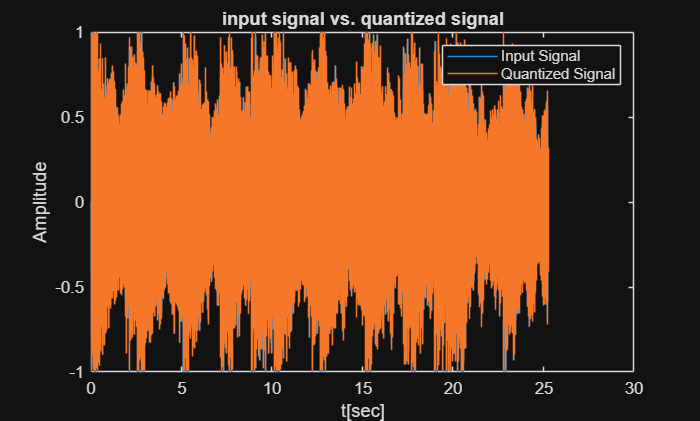

First 10 bits of the bit stream:
  1×10 int8 row vector

   0   1   1   1   1   1   1   1   0   1



[quantized_signal, mse, bit_stream, mp_max, mp_min, R] = quantizer(sampled_signal, time_vector, 256, 1);

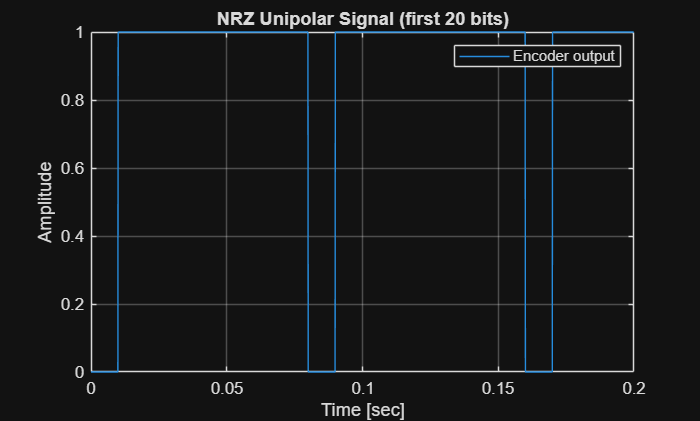

[encoded_signal, time_vector] = encoder(bit_stream,0,1,100,R,Fs,100);

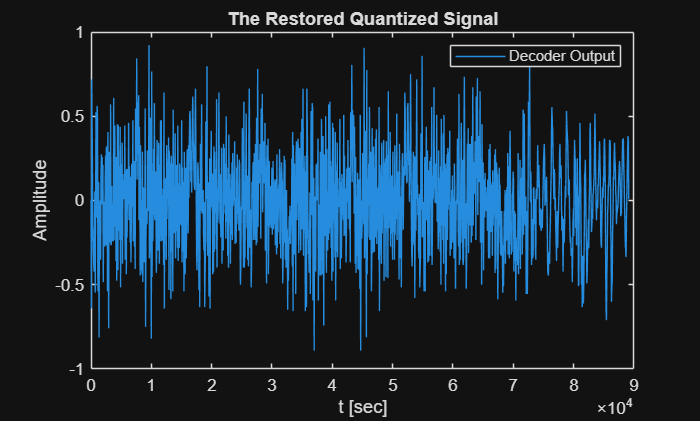

[restored_bit_stream, restored_quantized_signal] = decoder(time_vector,encoded_signal,mp_max,mp_min,256,1,0,100,1);

sound(restored_quantized_signal, Fs);